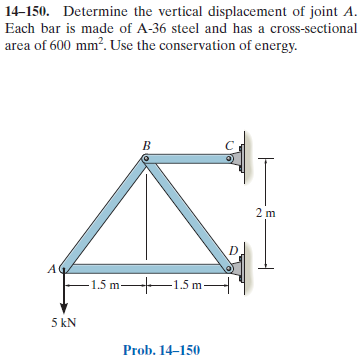

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-150RP-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-150RP-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = atand(sym(2/1.5))*u.deg;
jointA = [0 0]*u.m;
jointB = [1.5 2]*u.m;
jointC = [3 2]*u.m;
jointD = [3 0]*u.m;

# member data

E = 200*u.GPa;
A = 600*u.mm^2;

# truss

t = Truss;
t = t.add('reaction', 'Rc', {'Rcx' 'Rcy'}, jointC);
t = t.add('reaction', 'Rd', {'Rdx' 'Rdy'}, jointD);
t = t.add('concentrated', 'Pa', [0 -5]*u.kN, jointA);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('member', 'Fab', jointA, jointB, E, A);
t = t.add('member', 'Fad', jointA, jointD, E, A);
t = t.add('member', 'Fbc', jointB, jointC, E, A);
t = t.add('member', 'Fbd', jointB, jointD, E, A);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua_vpa = vpa(ua, 4) %#ok<NASGU> 

$$ua\_vpa = \left(\begin{array}{cc} \mathrm{uA} & 0.09375\,\mathrm{mm}\\ \mathrm{vA} & -0.5365\,\mathrm{mm}\\ \mathrm{uB} & -0.09375\,\mathrm{mm}\\ \mathrm{vB} & -0.2331\,\mathrm{mm}\\ \mathrm{uC} & 0\\ \mathrm{vC} & 0\\ \mathrm{uD} & 0\\ \mathrm{vD} & 0 \end{array}\right)$$

# forces on the truss

ma_f_m_vpa = vpa(ma.f.m) %#ok<NASGU>

$$ma\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & 6.25\,\mathrm{kN}\\ \mathrm{Fad} & -3.75\,\mathrm{kN}\\ \mathrm{Fbc} & 7.5\,\mathrm{kN}\\ \mathrm{Fbd} & -6.25\,\mathrm{kN} \end{array}\right)$$

la_f_c_vpa = vpa(la.f.c) %#ok<NASGU> 

$$la\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Rc} & 7.5\,\mathrm{kN} & 0 & 0\\ \mathrm{Rd} & -7.5\,\mathrm{kN} & 5.0\,\mathrm{kN} & 0\\ \mathrm{Pa} & 0 & -5.0\,\mathrm{kN} & 0 \end{array}\right)$$

ma_f_c_vpa = vpa(ma.f.c) %#ok<NASGU> 

$$ma\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Fab} & 3.75\,\mathrm{kN} & 5.0\,\mathrm{kN} & 0\\ \mathrm{Fad} & -3.75\,\mathrm{kN} & 0 & 0\\ \mathrm{Fbc} & 7.5\,\mathrm{kN} & 0 & 0\\ \mathrm{Fbd} & -3.75\,\mathrm{kN} & 5.0\,\mathrm{kN} & 0 \end{array}\right)$$

la_f_m_vpa = vpa(la.f.m, 3) %#ok<NASGU> 

$$la\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Rc} & 7.5\,\mathrm{kN}\\ \mathrm{Rd} & 9.01\,\mathrm{kN}\\ \mathrm{Pa} & 5.0\,\mathrm{kN} \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fad} & 0\\ \mathrm{Fbc} & 15\,\mathrm{kN}\,m\\ \mathrm{Fbd} & 15\,\mathrm{kN}\,m \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Rc} & 0 & 0 & -15\,\mathrm{kN}\,m\\ \mathrm{Rd} & 0 & 0 & 15\,\mathrm{kN}\,m\\ \mathrm{Pa} & 0 & 0 & 0 \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fad} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & -15\,\mathrm{kN}\,m\\ \mathrm{Fbd} & 0 & 0 & 15\,\mathrm{kN}\,m \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Rc} & 15\,\mathrm{kN}\,m\\ \mathrm{Rd} & 15\,\mathrm{kN}\,m\\ \mathrm{Pa} & 0 \end{array}\right)$$

# clean up

assume(old_assum);
clear old_assum;
clear ua_vpa;
clear ma_f_m_vpa ma_f_c_vpa la_f_c_vpa la_f_m_vpa;
clear ma_m_m la_m_c ma_m_c la_m_m;